# Problem Set 4

## Problem 1

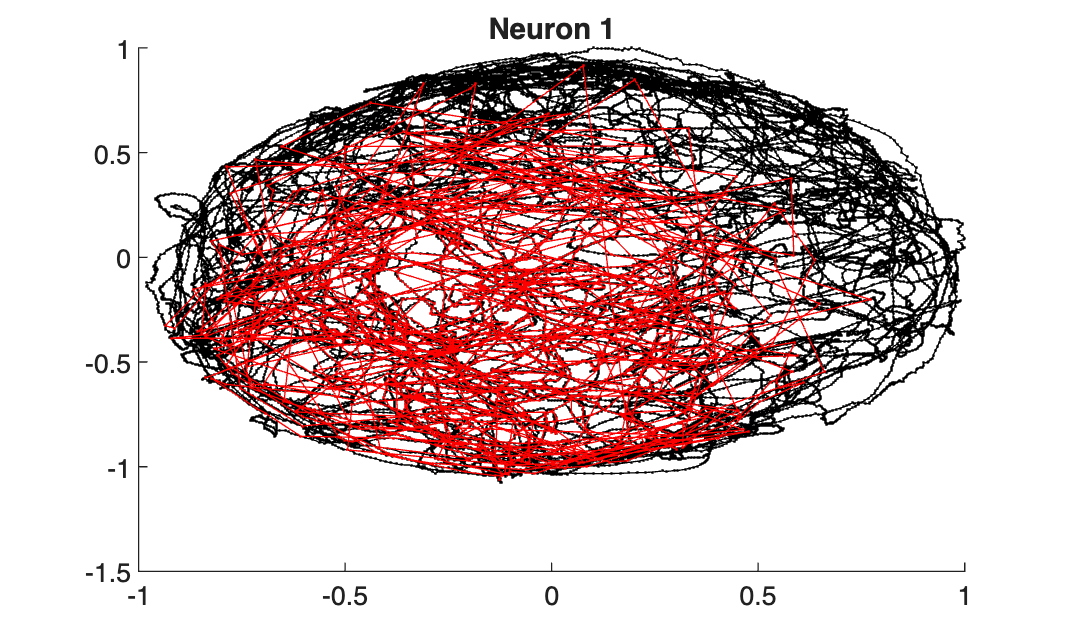

% Part A
figure;
hold on
plot(xN, yN, 'Marker', '.', 'Color', 'k', 'MarkerSize', 1)
spike_idx = find(spikes);
plot(xN(spike_idx), yN(spike_idx), 'Marker', '.', 'Color', 'r', 'MarkerSize', 1);
title('Neuron 1')

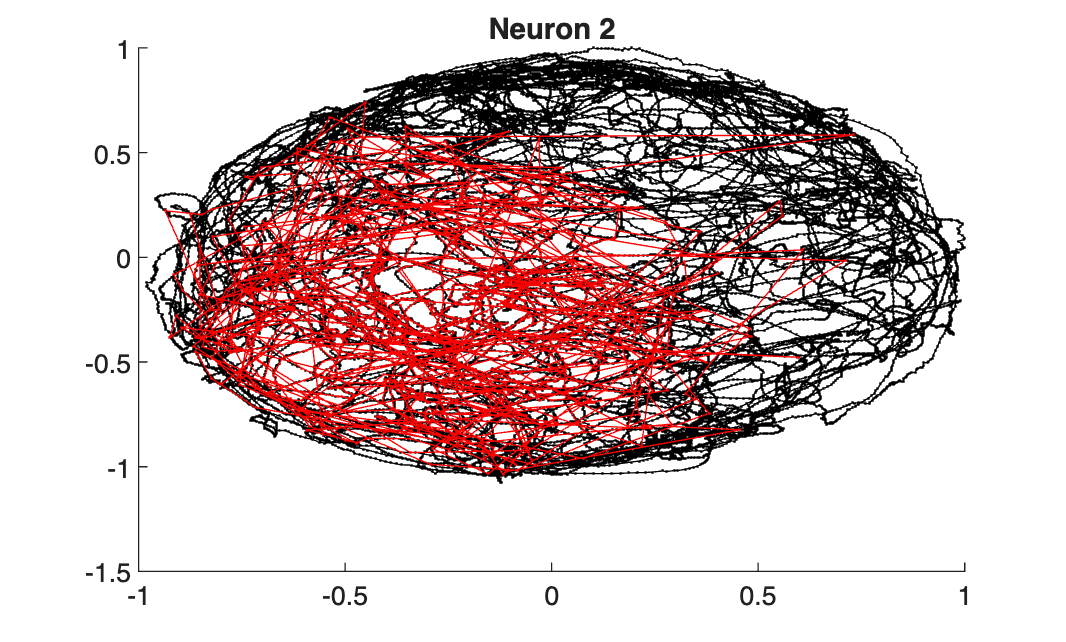


figure;
hold on
plot(xN, yN, 'Marker', '.', 'Color', 'k', 'MarkerSize', 1)
spike2_idx = find(spikes2);
plot(xN(spike2_idx), yN(spike2_idx), 'Marker', '.', 'Color', 'r', 'MarkerSize', 1);
title('Neuron 2')

The spatial firing properties of the two neurons

% Part B
[b,dev,stats] = glmfit([xN yN],spikes,'poisson');
% b = maximum likelihood estimate [b_0, b_1, b_2]
% dev = model deviance (dev = -2log(theta))
% stats.se = standard error
% stats.p = p-values
disp(stats.p)

   1.0e-26 *

         0
    0.8482
    0.0000



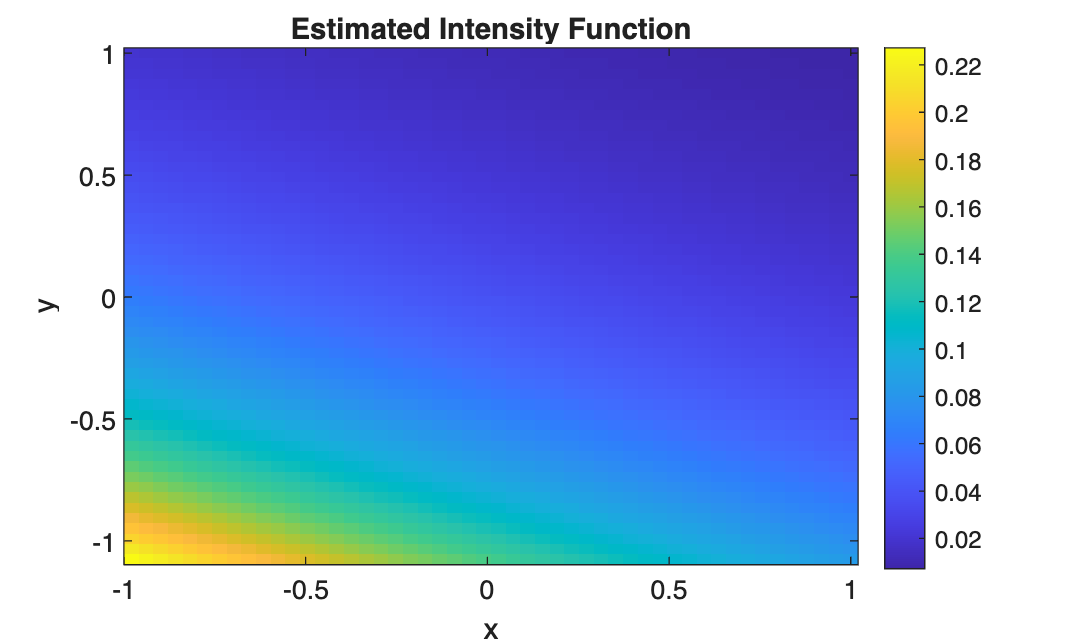

[xgrid, ygrid] = meshgrid(linspace(min(xN), max(xN), 50), ...
                         linspace(min(yN), max(yN), 50));

lambda = exp(b(1) + b(2)*xgrid + b(3)*ygrid);

figure;
imagesc(linspace(min(xN), max(xN), 50), ...
        linspace(min(yN), max(yN), 50), lambda);
axis xy;
colorbar;
title('Estimated Intensity Function');
xlabel('x'); ylabel('y');

The resulting parameters estimates are significant

% Part C
X = [xN yN xN.^2 yN.^2 xN.*yN];

[b, dev, stats] = glmfit(X, spikes, 'poisson');
disp(stats.p)

         0
    0.0000
    0.0000
    0.0000
    0.0000
    0.6196



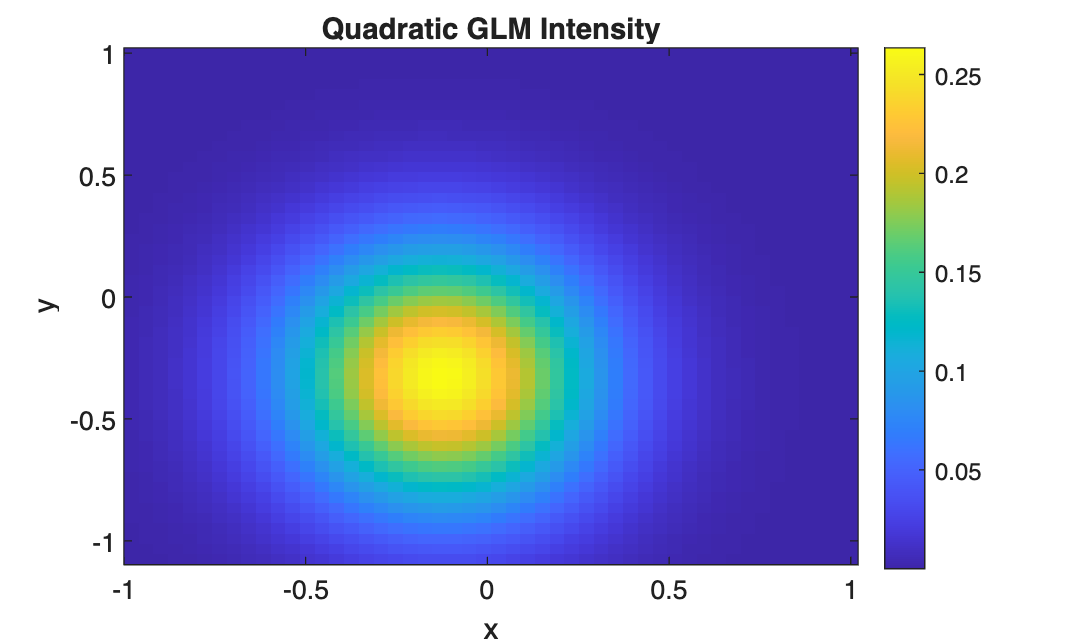

[xgrid, ygrid] = meshgrid(linspace(min(xN), max(xN), 50), ...
                         linspace(min(yN), max(yN), 50));

lambda = exp(b(1) + ...
             b(2)*xgrid + ...
             b(3)*ygrid + ...
             b(4)*xgrid.^2 + ...
             b(5)*ygrid.^2 + ...
             b(6)*xgrid.*ygrid);

figure;
imagesc(linspace(min(xN), max(xN), 50), ...
        linspace(min(yN), max(yN), 50), lambda);
axis xy;
colorbar;
title('Quadratic GLM Intensity');
xlabel('x'); ylabel('y');

## Problem 2

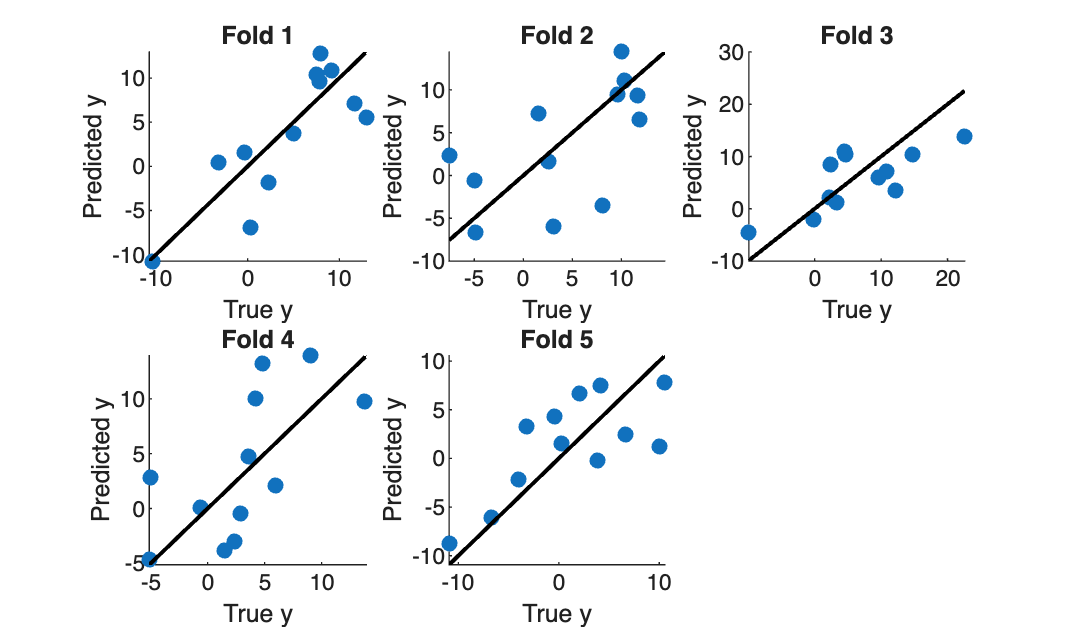

Fold 1: Train VAF = 0.807, Test VAF = 0.721
Fold 2: Train VAF = 0.844, Test VAF = 0.446
Fold 3: Train VAF = 0.796, Test VAF = 0.720
Fold 4: Train VAF = 0.827, Test VAF = 0.317
Fold 5: Train VAF = 0.828, Test VAF = 0.531


% Part A
% predictors X1, outcomes y1

% part i
cv = cvpartition(length(y1), 'KFold', 5);
num_folds = cv.NumTestSets;
error = zeros(num_folds, 1);
VAF_train = zeros(num_folds, 1);
VAF_test  = zeros(num_folds, 1);

figure;
for fold = 1:num_folds
    trainInd = training(cv, fold);
    testInd = test(cv, fold);

    Xtrain = X1(trainInd, :);
    ytrain = y1(trainInd);
    Xtest = X1(testInd, :);
    ytest = y1(testInd);

    Xtrain = [ones(size(Xtrain, 1), 1), Xtrain];
    Xtest = [ones(size(Xtest, 1), 1), Xtest];

    b = Xtrain \ ytrain;
    ypred_test = Xtest * b;
    ypred_train = Xtrain * b;

    % part iii
    VAF_train(fold) = 1 - sum((ytrain - ypred_train).^2) / sum(ytrain.^2);
    VAF_test(fold) = 1 - sum((ytest - ypred_test).^2) / sum(ytest.^2);
    fprintf('Fold %d: Train VAF = %.3f, Test VAF = %.3f\n', ...
            fold, VAF_train(fold), VAF_test(fold));

    % part ii
    subplot(2,3,fold);
    scatter(ytest, ypred_test, 'filled'); hold on;
    minVal = min([ytest; ypred_test]);
    maxVal = max([ytest; ypred_test]);
    plot([minVal maxVal], [minVal maxVal], 'k-', 'LineWidth', 1.5);
    xlabel('True y');
    ylabel('Predicted y');
    title(['Fold ' num2str(fold)]);
    
    error(fold) = mean((ytest - ypred_test).^2);
end


mean_error = mean(error);
disp(mean_error);

   24.8337



mean_train_VAF = mean(VAF_train);
mean_test_VAF  = mean(VAF_test);

fprintf('Average Train VAF = %.3f\n', mean_train_VAF);

Average Train VAF = 0.820


fprintf('Average Test VAF  = %.3f\n', mean_test_VAF);

Average Test VAF  = 0.547


part iv: The Train VAF and the test VAF